# `GPS Position Plotting and Updating in a sequence for logged data`

`Enter The location of your logged data in .mat format below`

`For example: data = load('/home/hazem/MATLAB-Drive/MobileSensorData/sensorlog_Oct24_1.mat')`

% Load the data
data = load('/home/hazem/MATLAB-Drive/MobileSensorData/sensorlog_Oct23_1.mat');

% Store needed data in vectors to be used in plotting
latitudes = data.Position.latitude;
longitudes = data.Position.longitude;
altitude = data.Position.altitude;
accuracies = data.Position.hacc;  % Horizontal accuracy
markerSizes = accuracies .* 10;
timestamps = seconds(diff(data.Position.Timestamp));  % Time differences between points

% Parameters
accuracyThreshold = 40;  % Exclude points with accuracy > 40 meters
pointsPerCurve = 3;  % Fit curve over 3 points
degree = 2;  % 2nd-degree polynomial

% Filter out points with accuracy > 60 meters
validIndices = accuracies <= accuracyThreshold;
latitudes = latitudes(validIndices);
longitudes = longitudes(validIndices);
markerSizes = markerSizes(validIndices);

`And now we create the figure for GPS Coordinates plotting in a geobasemap.`

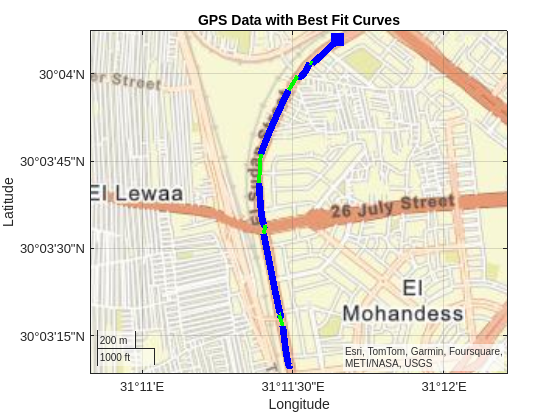

% Set up the geographic plot and base map
figure;
geobasemap('streets');  % Set the map to street view
hold on;

% Initialize the plot with the first point
geoscatter(latitudes(1), longitudes(1), markerSizes(1), "blue", "filled", "square");
title('GPS Data with Best Fit Curves');
bestFitLineHandle = [];

% Iterate through data, fitting and connecting curves every 5 points
for i = pointsPerCurve:pointsPerCurve:length(latitudes)
    % Fit a 2nd-degree polynomial to the current chunk of 5 points
    latChunk = latitudes(i-pointsPerCurve+1:i);
    lonChunk = longitudes(i-pointsPerCurve+1:i);
    
    pLat = polyfit(1:pointsPerCurve, latChunk', degree);
    pLon = polyfit(1:pointsPerCurve, lonChunk', degree);
    
    % Generate smooth data points for plotting the curve
    fitPoints = linspace(1, pointsPerCurve, 100);
    latFit = polyval(pLat, fitPoints);
    lonFit = polyval(pLon, fitPoints);
    
    % Plot the fitted curve on the geobasemap
    geoplot(latFit, lonFit, 'b', 'LineWidth', 5);
    
    % Convert best fit curve to ENU coordinates using lla2enu
    refLat = latitudes(1);  % Reference latitude (first point)
    refLon = longitudes(1);  % Reference longitude (first point)
    refAlt = altitude(1);  % Assuming altitude = 0 for simplicity
    lla = [latFit', lonFit', zeros(size(latFit))'];  % Create LLA matrix
    
    % Use the lla2enu function to convert to ENU coordinates
    enu = lla2enu(lla, [refLat, refLon, refAlt], 'ellipsoid');
    
    % Print ENU details (optional)
    % disp('ENU Coordinates:');
    % disp(enu);
    
    % Plot the connecting line between the end of the previous curve and the start of the next one
    if i > pointsPerCurve
        % Connecting previous curve's last point with current curve's first point
        geoplot([latitudes(i-pointsPerCurve), latitudes(i-pointsPerCurve+1)], ...
                [longitudes(i-pointsPerCurve), longitudes(i-pointsPerCurve+1)], 'g', 'LineWidth', 3);
    end
    
    % Optional pause for real-time plotting (can use timestamps for actual time)
    pause(5);
end

hold off;